# **Otonom Araçları için kaza riski analizi**

## **Alabileceğimiz girişler:**

**Arabanın hızı**, Arabanın ağırlığı, **kalan mesafe**, hava durumu

## **Rules tables:**

**Dist\Speed  Slow           Fast            VeryFast**

**Far**               0                 0.25             0.5

**Close**           0.25            0.5               0.75

**VeryClose   **0.5              0.75             1

%global X mu_X mu_xi;
altsinir_x = 0;
ustsinir_x = 100;
altsinir_y = 0;
ustsinir_y = 100;
altsinir_z = 0;
ustsinir_z = 100;

xi = 30;
yi = 3;
zi = 0;

a = 0; b = 0;

b1 = 1


XX = altsinir_x:ustsinir_x;
YY = altsinir_y:ustsinir_y;
%ZZ = altsinir_z:ustsinir_z;
z = zeros(size(XX,2),size(YY,2));

tic
parfor i=1:size(XX,2)
    z_tmp = zeros(1,size(YY,2))
    for j=1:size(YY,2)
        toplam_agirlik = 0;
        xi=XX(i);
        yi=YY(j);
        %% Inputs and Outputs Membership Functions
        % input 1
        [x_S, mu_S, mu_xi_S] = Yamuk(altsinir_x,0,0,20,40,ustsinir_x,xi);
        [x_F, mu_F, mu_xi_F] = Yamuk(altsinir_x,20,40,60,80,ustsinir_x,xi);
        [x_VF, mu_VF, mu_xi_VF] = Yamuk(altsinir_x,60,80,100,100,ustsinir_x,xi); 
        
        % input 2
        [y_F, mu_F, mu_yi_F] = Yamuk(altsinir_y,0,0,20,40,ustsinir_y,yi);
        [y_C, mu_C, mu_yi_C] = Yamuk(altsinir_y,20,40,60,80,ustsinir_y,yi);
        [y_VC, mu_VC, mu_yi_VC] = Yamuk(altsinir_y,60,80,100,100,ustsinir_y,yi);
        
        % output
        z1 = a*xi + b*yi + 0;
        z2 = a*xi + b*yi + 0.25;
        z3 = a*xi + b*yi + 0.5;
        z4 = a*xi + b*yi + 0.25;
        z5 = a*xi + b*yi + 0.5;
        z6 = a*xi + b*yi + 0.75;
        z7 = a*xi + b*yi + 0.5;
        z8 = a*xi + b*yi + 0.75;
        z9 = a*xi + b*yi + 1;
        
        %% Fuzzy rules
        
        w1 = min(mu_xi_S,mu_yi_F);
        w2 = min(mu_xi_S,mu_yi_C);
        w3 = min(mu_xi_S,mu_yi_VC);

        w4 = min(mu_xi_F,mu_yi_F);
        w5 = min(mu_xi_F,mu_yi_C);
        w6 = min(mu_xi_F,mu_yi_VC);
        
        w7 = min(mu_xi_VF,mu_yi_F);
        w8 = min(mu_xi_VF,mu_yi_C);
        w9 = min(mu_xi_VF,mu_yi_VC);
        
        %% Results
        z_all = [z1 z2 z3 z4 z5 z6 z7 z8 z9];
        w_all = [w1 w2 w3 w4 w5 w6 w7 w8 w9];
        SAT = sum(w_all.*z_all);
       

        %plot(X,mu_birlestirme);
        
        %% defuzzification
        toplam_agirlik = sum(w_all);
        if toplam_agirlik == 0
            'Toplam Agirlik sifir!';
        end
        z_tmp(j) = SAT/toplam_agirlik;
    end %j
    z(i,:) = z_tmp;
end %i
toc

Elapsed time is 77.087352 seconds.


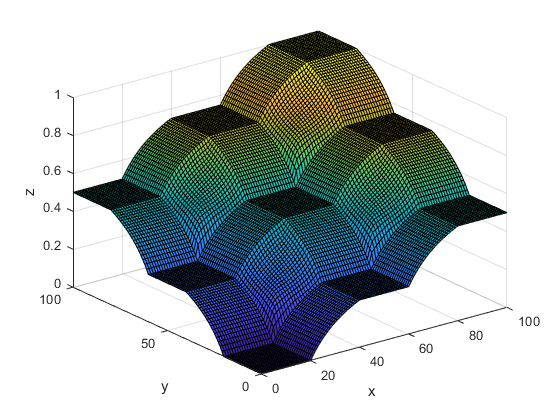

[x,y] = meshgrid(XX,YY);
surf(x,y,z')
xlabel('x');
ylabel('y');
zlabel('z');